
st_meritev = 100;
zacetna_ocena = [2, 2];
tol = 1e-5; % toleranca za konvergenco
bazne_postaje = [1, 1; 10, 5; 2, 4];  % koordinate treh baznih postaj
ponovitve = 100;

% Pridobivanje meritev razdalj do posameznih stolpov
meritve = measurments(st_meritev);    % dobimo 100 meritev

% graf razdalj telefona do posameznega stolpa
% razdalje od posameznega stolpa do telefona
figure;
plot(meritve);


## Izris N meritev posameznih stolpov


% Definicija barv za posamezne krivulje
colors = ['r', 'g', 'b'];  % rdeča, zelena, modra

% Izris grafa
figure;
hold on;

% Izris baznih postaj
plot(bazne_postaje(:,1), bazne_postaje(:,2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
for i = 1:size(bazne_postaje, 1)
    text(bazne_postaje(i, 1), bazne_postaje(i, 2), sprintf(' BS%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Izris krožnic okoli baznih postaj
theta = linspace(0, 2*pi, 100);  % Parametri za izris krožnice
for i = 1:size(bazne_postaje, 1)
    for j = 1:size(meritve, 1)
        x_circle = bazne_postaje(i, 1) + meritve(j, i) * cos(theta);
        y_circle = bazne_postaje(i, 2) + meritve(j, i) * sin(theta);
        plot(x_circle, y_circle, 'Color', colors(i));
    end
end

% Dodajanje legende in označb

title('Izris baznih postaj in krožnic na osnovi meritev');
xlabel('X koordinata');
ylabel('Y koordinata');
axis equal;  % Za enakomerno razmerje osi

hold off;



## Brez upoštevanja variance

% enakovredne meritve stolpov
utezi = [1, 1, 1];

% inicializiramo matrike za priblizke, variance, st_korakov pa napako
[priblizek, varianca] = deal(zeros(st_meritev, 2));
[st_korakov, napaka] = deal(zeros(st_meritev, 1));

% Optimizacija
for i = 1:st_meritev    % 100x

    % korak optimizacije pozicije
    % vrne oceno pozicije, kovariančno matriko, st iteracij za konergenco,
    % napako
    [pozicija, kovarianca, koraki, error] = levenberg_marquardt(zacetna_ocena, bazne_postaje, meritve(1:i, :), ponovitve, tol, utezi, @Funckija_JF);
    priblizek(i, :) = pozicija;    % približek gre v i-to vrstico
   
    % izračun standardnega odklona iz kovariančne matrike
    std_dev = diag(kovarianca);
    varianca(i, :) = sqrt(std_dev);
    st_korakov(i) = koraki;
    napaka(i) = error;
    
    if i == st_meritev
        variance_stolpov = varianca(i, :);
    end
end


## Prikaz resultatov (brez upoštevanja variance)


% Definicija barv za posamezne krivulje
colors = ['r', 'g', 'b'];  % rdeča, zelena, modra

% Izris grafa
figure;
hold on;

% Izris baznih postaj
plot(bazne_postaje(:,1), bazne_postaje(:,2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
for i = 1:size(bazne_postaje, 1)
    text(bazne_postaje(i, 1), bazne_postaje(i, 2), sprintf(' BS%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Izris krožnic okoli baznih postaj
theta = linspace(0, 2*pi, 100);  % Parametri za izris krožnice
for i = 1:size(bazne_postaje, 1)
    for j = 1:size(meritve, 1)
        x_circle = bazne_postaje(i, 1) + meritve(j, i) * cos(theta);
        y_circle = bazne_postaje(i, 2) + meritve(j, i) * sin(theta);
        plot(x_circle, y_circle, 'Color', colors(i));
    end
end

% Dodajanje legende in označb
title('Izris baznih postaj in krožnic na osnovi meritev');
xlabel('X koordinata');
ylabel('Y koordinata');
axis equal;  % Za enakomerno razmerje osi

% Prikaz končne pozicije telefona
koncna_pozicija = priblizek(end, :);
plot(koncna_pozicija(1), koncna_pozicija(2), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 10);
text(koncna_pozicija(1), koncna_pozicija(2), ' Končna pozicija', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

hold off;


% Izris spreminjanja X komponente predvidene lokacije
figure;
subplot(2, 1, 1);  % Ustvari dve ploskvi v eni figuri, to je prva
plot(1:st_meritev, priblizek(:, 1), 'r.-', 'MarkerSize', 10);
title('Spreminjanje X komponente predvidene lokacije skozi iteracije');
xlabel('Število iteracij');
ylabel('X koordinata');
grid on;

% Izris spreminjanja Y komponente predvidene lokacije
subplot(2, 1, 2);  % Druga ploskev v isti figuri
plot(1:st_meritev, priblizek(:, 2), 'b.-', 'MarkerSize', 10);
title('Spreminjanje Y komponente predvidene lokacije skozi iteracije');
xlabel('Število iteracij');
ylabel('Y koordinata');
grid on;

% Izpis končne lokacije iskanega predmeta
disp('Končna predvidena lokacija iskanega predmeta:');
disp(['X koordinata: ', num2str(koncna_pozicija(1))]);
disp(['Y koordinata: ', num2str(koncna_pozicija(2))]);

% Izpis števila korakov za konvergenco brez upoštevanja variance
disp('Število korakov za konvergenco (brez upoštevanja variance):');
disp(st_korakov(end));


## Z upoštevanjem variance

% Calculate the weights based on the inverse variance of the measurements
weights = 1 ./ var(meritve, 0, 1);  % Inverse of variance for each base station

% Initialize matrices for approximations, variances, number of steps, and errors
[priblizek_var, varianca_var] = deal(zeros(st_meritev, 2));
[st_korakov_var, napaka_var] = deal(zeros(st_meritev, 1));

% Weighted optimization
for i = 1:st_meritev
    % Optimization step with variance weights
    [pozicija_var, kovarianca_var, koraki_var, error_var] = levenberg_marquardt(zacetna_ocena, bazne_postaje, meritve(1:i, :), ponovitve, tol, weights, @Funckija_JF);
    priblizek_var(i, :) = pozicija_var;
    
    % Calculate standard deviation from covariance matrix
    std_dev_var = diag(kovarianca_var);
    varianca_var(i, :) = sqrt(std_dev_var);
    st_korakov_var(i) = koraki_var;
    napaka_var(i) = error_var;
    
    if i == st_meritev
        variance_stolpov_var = varianca_var(i, :);
    end
end

% Display the results (with variance consideration)
disp('Weighted Results:');

Weighted Results:


disp('Final predicted location of the object:');

Final predicted location of the object:


disp(['X coordinate: ', num2str(priblizek_var(end, 1))]);

X coordinate: 5.2033


disp(['Y coordinate: ', num2str(priblizek_var(end, 2))]);

Y coordinate: 2.1008



disp('Number of steps for convergence (with variance):');

Number of steps for convergence (with variance):


disp(st_korakov_var(end));

     6



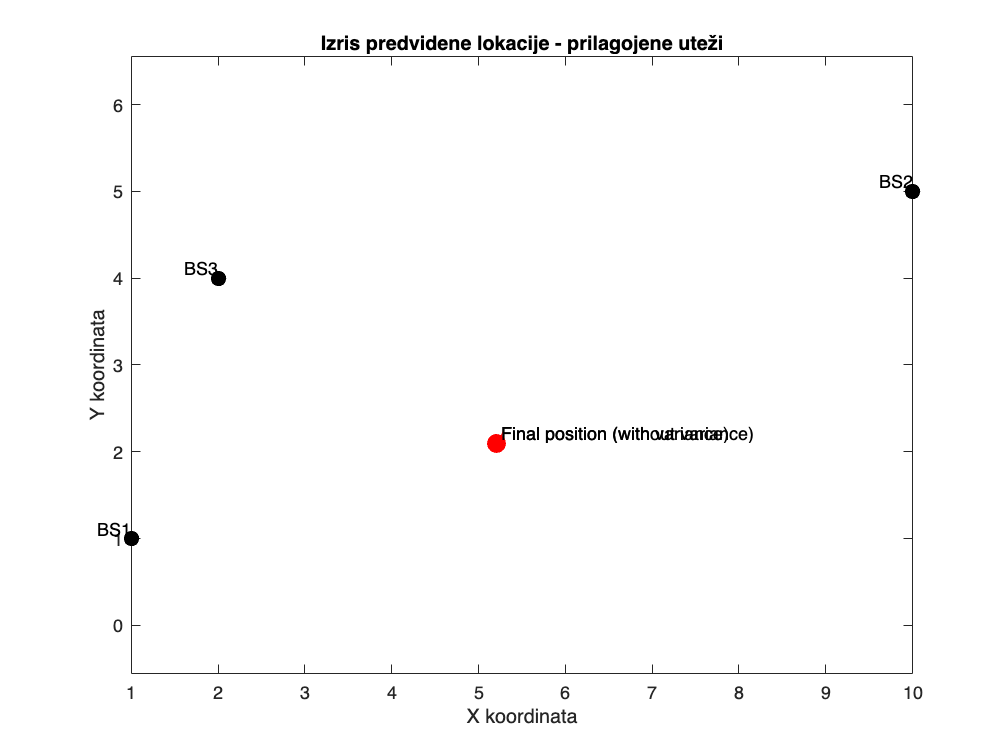


% Plotting (with variance consideration)

% Plotting the base stations
figure;
plot(bazne_postaje(:,1), bazne_postaje(:,2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
hold on;
for i = 1:size(bazne_postaje, 1)
    text(bazne_postaje(i, 1), bazne_postaje(i, 2), sprintf(' BS%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Plotting the estimated path without considering variance (blue line)
plot(priblizek_var(:, 1), priblizek_var(:, 2), 'b--');
plot(priblizek_var(end, 1), priblizek_var(end, 2), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 10);
text(priblizek_var(end, 1), priblizek_var(end, 2), ' Final position (without variance)', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

% Plotting the estimated path considering variance (red line)
plot(priblizek_var(:, 1), priblizek_var(:, 2), 'r--');
plot(priblizek_var(end, 1), priblizek_var(end, 2), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
text(priblizek_var(end, 1), priblizek_var(end, 2), ' Final position (with variance)', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

% Adding legend and labels
title('Izris predvidene lokacije - prilagojene uteži');
xlabel('X koordinata');
ylabel('Y koordinata');
axis equal;  % To maintain equal aspect ratio
%legend('Base Station', 'Path without variance', 'Final position (without variance)', 'Path with variance', 'Final position (with variance)');
hold off;

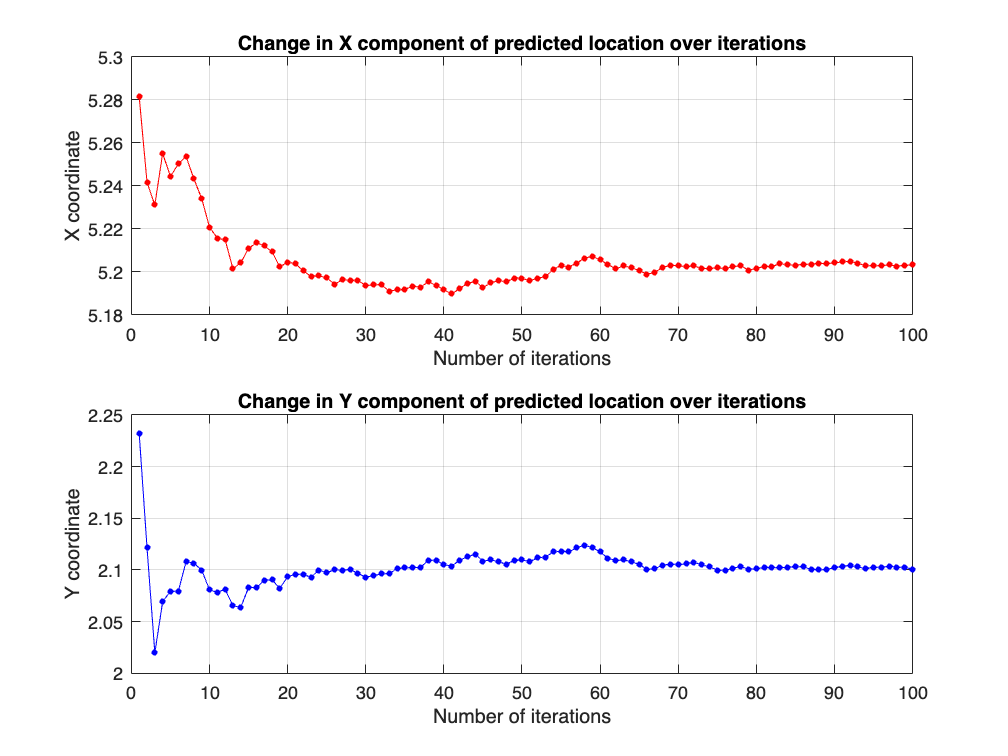


% Plotting the change in X and Y components of the predicted location over iterations
figure;
subplot(2, 1, 1);  % Create two plots in one figure, this is the first one
plot(1:st_meritev, priblizek_var(:, 1), 'r.-', 'MarkerSize', 10);
title('Spreminjanje X komponente predvidene lokacije skozi iteracije');
xlabel('Spreminjanje Y komponente predvidene lokacije skozi iteracije');
ylabel('X coordinate');
grid on;

subplot(2, 1, 2);  % Second plot in the same figure
plot(1:st_meritev, priblizek_var(:, 2), 'b.-', 'MarkerSize', 10);
title('Change in Y component of predicted location over iterations');
xlabel('Number of iterations');
ylabel('Y coordinate');
grid on;

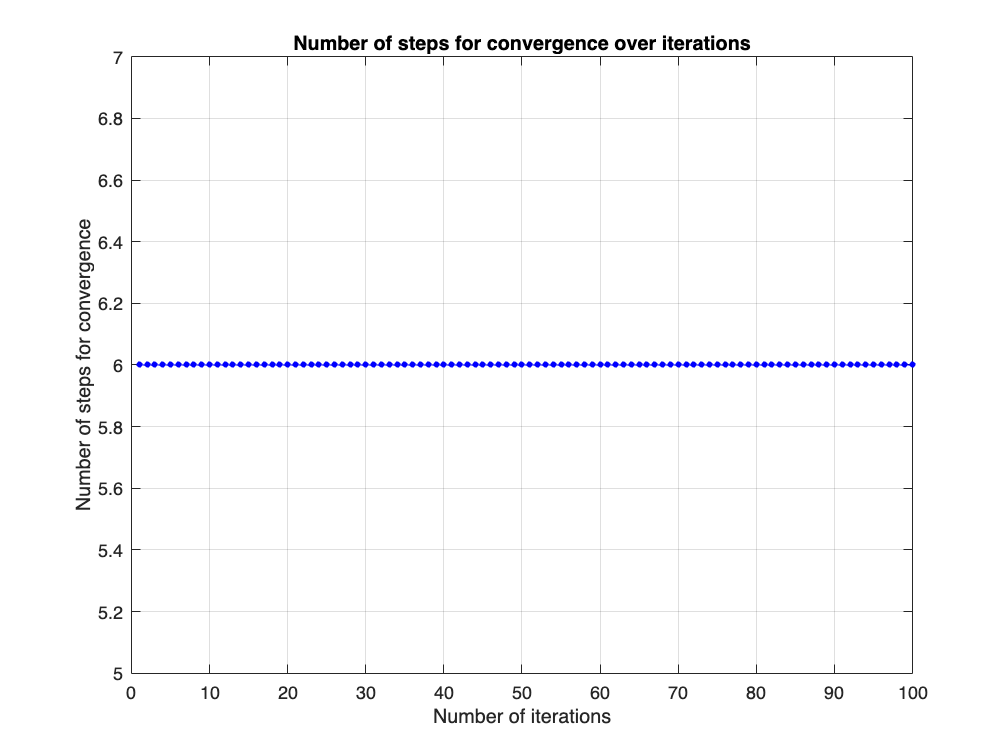


% Plotting the number of steps for convergence over iterations
figure;
plot(1:st_meritev, st_korakov_var, 'b.-', 'MarkerSize', 10);
title('Number of steps for convergence over iterations');
xlabel('Number of iterations');
ylabel('Number of steps for convergence');
grid on;


% Displaying the final location of the object
disp('Final predicted location of the object:');

Final predicted location of the object:


disp(['X coordinate: ', num2str(priblizek_var(end, 1))]);

X coordinate: 5.2033


disp(['Y coordinate: ', num2str(priblizek_var(end, 2))]);

Y coordinate: 2.1008



% Calculating and displaying the standard deviation for the final position
koncni_std_odklon_var = varianca_var(end, :);
disp('Standard deviation of the final predicted location of the object:');

Standard deviation of the final predicted location of the object:


disp(['Standard deviation X coordinate: ', num2str(koncni_std_odklon_var(1))]);

Standard deviation X coordinate: 3497.8432


disp(['Standard deviation Y coordinate: ', num2str(koncni_std_odklon_var(2))]);

Standard deviation Y coordinate: 2010.4995



% Displaying the number of steps for convergence with variance consideration
disp('Number of steps for convergence (with variance consideration):');

Number of steps for convergence (with variance consideration):


disp(st_korakov_var(end));

     6



## Prikaz rezultatov (upoštevanje variance)


% Izris baznih postaj
figure;
plot(bazne_postaje(:,1), bazne_postaje(:,2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
hold on;
for i = 1:size(bazne_postaje, 1)
    text(bazne_postaje(i, 1), bazne_postaje(i, 2), sprintf(' BS%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Izris poti brez upoštevanja variance (modra barva)
plot(priblizek_var(:, 1), priblizek_var(:, 2), 'b--');
plot(priblizek_var(end, 1), priblizek_var(end, 2), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 10);
text(priblizek_var(end, 1), priblizek_var(end, 2), ' Končna pozicija (brez variance)', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

% Izris poti z upoštevanjem variance (rdeča barva)
plot(priblizek_var(:, 1), priblizek_var(:, 2), 'r--');
plot(priblizek_var(end, 1), priblizek_var(end, 2), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
text(priblizek_var(end, 1), priblizek_var(end, 2), ' Končna pozicija (z varianco)', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

% Dodajanje legende in označb
title('Izris baznih postaj in končne pozicije telefona');
xlabel('X koordinata');
ylabel('Y koordinata');
axis equal;  % Za enakomerno razmerje osi
legend('Bazna postaja', 'Pot brez variance', 'Končna pozicija (brez variance)', 'Pot z varianco', 'Končna pozicija (z varianco)');
hold off;

% Izris spreminjanja X in Y komponente predvidene lokacije skozi iteracije
figure;
subplot(2, 1, 1);  % Ustvari dve ploskvi v eni figuri, to je prva
plot(1:st_meritev, priblizek_var(:, 1), 'r.-', 'MarkerSize', 10);
title('Spreminjanje X komponente predvidene lokacije skozi iteracije');
xlabel('Število iteracij');
ylabel('X koordinata');
grid on;

subplot(2, 1, 2);  % Druga ploskev v isti figuri
plot(1:st_meritev, priblizek_var(:, 2), 'b.-', 'MarkerSize', 10);
title('Spreminjanje Y komponente predvidene lokacije skozi iteracije');
xlabel('Število iteracij');
ylabel('Y koordinata');
grid on;

% Izris števila korakov za konvergenco skozi iteracije
figure;
plot(1:st_meritev, st_korakov, 'b.-', 'MarkerSize', 10);
title('Število korakov za konvergenco skozi iteracije');
xlabel('Število iteracij');
ylabel('Število korakov za konvergenco');
grid on;

% Izpis končne lokacije iskanega predmeta
disp('Končna predvidena lokacija iskanega predmeta:');
disp(['X koordinata: ', num2str(priblizek(end, 1))]);
disp(['Y koordinata: ', num2str(priblizek(end, 2))]);

% Izračun standardnega odklona za končno pozicijo
koncni_std_odklon = varianca(end, :);

% Izpis standardnega odklona
disp('Standardni odklon končne predvidene lokacije iskanega predmeta:');
disp(['Standardni odklon X koordinata: ', num2str(koncni_std_odklon(1))]);
disp(['Standardni odklon Y koordinata: ', num2str(koncni_std_odklon(2))]);

% Izpis števila korakov za konvergenco z upoštevanjem variance
disp('Število korakov za konvergenco (z upoštevanjem variance):');
disp(st_korakov_var(end));


function pings = measurments(num_pings)
    pings = [];
    for i = 1:num_pings
        pings = [pings; ping_stolp_1(), ping_stolp_2(), ping_stolp_3()];
    end
end

function [J, f] = Funckija_JF(parametri, w, bazne_postaje, meritve)
    N = size(meritve, 1); % Število meritev
    f = zeros(N * 3, 1); % Inicializacija vektorja funkcije napake
    J = zeros(N * 3, 2); % Inicializacija Jakobijeve matrike

    x = parametri(1);
    y = parametri(2);
    
    for i = 1:N
        for j = 1:size(bazne_postaje, 1)
            % Izračun pričakovane razdalje od trenutnih koordinat do bazne postaje
            d = sqrt((x - bazne_postaje(j, 1))^2 + (y - bazne_postaje(j, 2))^2);
            % Izračun funkcije napake
            f((i-1)*3 + j) = (d - meritve(i, j))*w(j);
            % Izračun Jakobijeve matrike
            J((i-1)*3 + j, 1) = ((x - bazne_postaje(j, 1)) / d)*w(j);
            J((i-1)*3 + j, 2) = ((y - bazne_postaje(j, 2)) / d)*w(j);
        end
    end
end

function [param, covariance, steps, err] = levenberg_marquardt(parametri, bazne_postaje, meritve, N, tol, w, Funckija_JF)
    param = parametri;
    alpha = 0.01;
    iter = 0;

    for iter = 1:N
        [J, f] = Funckija_JF(param, w, bazne_postaje, meritve);
        H = J' * J + alpha * eye(length(param));
        d_param = -H \ (J' * f);
        param = param + d_param';
        if norm(d_param) < tol
            break;
        end
    end

    covariance = J' * J;
    steps = iter;
    err = f' * f;
end
